# Creación de señal bineada

clear
% Información del archivo .h5
path = "..\hdf5\A_RS_140819\LFP.h5";
filename = strrep(path, '\', '\\');
dataset = '/LFP';
info = h5info(filename, dataset);
num_times = info.Dataspace.Size(1);

signal = h5read(filename, dataset, [1 1], [977289 1024]);
z_score=(signal-mean(signal, 1))./std(signal, 1, 1);

Número de tiempos = `977289`

Calcular bineado en 1s y 10s.

f = 500; % [Hz]
t_bin = 0.01; % [s]
points_bin = t_bin*f;
points_all = size(z_score, 1);
n_bins = ceil(points_all / points_bin);
n_electrodes = size(z_score, 2);

binned_z_score = zeros(n_bins, n_electrodes);
for b=0:n_bins-1
    ini = b*points_bin+1;
    fin = min((b+1)*points_bin, points_all);
    binned_z_score(b+1, :) = mean(z_score(ini:fin, :), 1);
end

filename=sprintf("binned_%.2fs_z_score_A_RS_140819_LFP.mat", t_bin);
save(filename, "binned_z_score");

# Agora sim

load('..\\A_electrode_positions.mat', 'positions_arr')
load("binned_0.01s_z_score_A_RS_140819_LFP.mat", "binned_z_score");

thresh = .5;
t=1;
dr = 1600;

active_electrodes = binned_z_score>thresh;
X = positions_arr(active_electrodes(t, :), :); % posiciones de electrodos activos
corners = corners_of_arrays(positions_arr);

[corrfun, r, rw] = twopointcorr(X(:, 1),X(:, 2), dr); % 2 pt corr para ese dado threshold

p = polyfit(log10(r(corrfun>0)), log10(corrfun(corrfun>0)), 1); % ajuste para sacar exponente eta
x1 = log10(min(r)); x2 = log10(max(r)); y1 = polyval(p, x1); y2 = polyval(p, x2);
eta = p(1);
filename = sprintf("twopointcorr&positions_t%.2f_threshold%.2f.mat", t, thresh);
save(filename, "X", "corners", "r", "corrfun", "x1", "x2", "y1", "y2", "eta");

thresh = 0.5;
t=1;

filename = sprintf("twopointcorr&positions_t%.2f_threshold%.2f.mat", t, thresh);
load(filename, "X", "corners", "r", "corrfun", "x1", "x2", "y1", "y2", "eta");

Error using load
Unable to find file or directory 'twopointcorr&positions_t1.00_threshold0.50.mat'.


clear figure
figure('units','normalized','outerposition',[0 0 1 1])
target = tiledlayout(2,1);


nexttile;
scatter(X(:,1), X(:,2), '.');

hold on
for arr=1:16
    plot(corners(arr,:,1), corners(arr,:,2), 'r'); % aca ploteo los bordes de los arrays
end
axis padded equal
xlabel("$x\; [\mu m]$", "Interpreter", "latex");
ylabel("$y\; [\mu m]$", "Interpreter", "latex");
hold off


nexttile;
plot(log10(r), log10(corrfun), '--o');

hold on
plot([x1 x2], [y1 y2]);
legend(["data" sprintf("$\\eta=%.2f$", eta)], Interpreter="latex", Location="southwest");

grid on
axis padded
xlabel("$log(r)\; [\mu m]$", "Interpreter", "latex");
ylabel("$log_{10}(g^{(2)}(r))$", "Interpreter", "latex");
hold off

filename = sprintf("figuras\\twopointcorr&positions_t%.2f_threshold%.2f.png", t, thresh);
exportgraphics(target, filename);

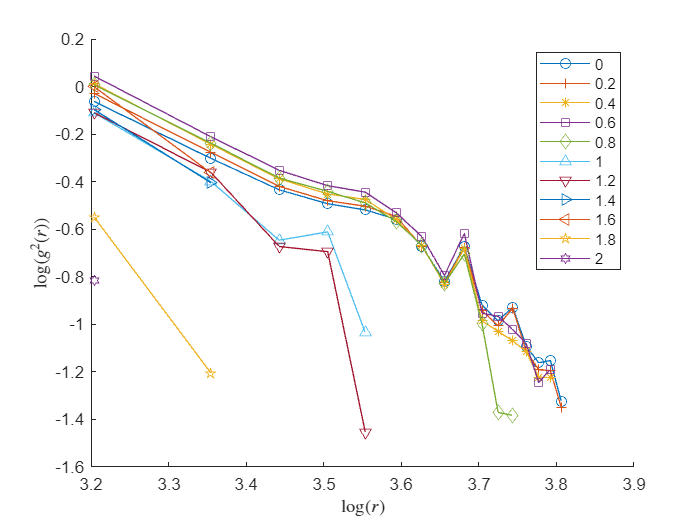

thresholds = 0:0.2:2;
dr = 1600;

clear figure
figure

X = positions_arr;
[corrfun_total, r_total, ~] = twopointcorr(X(:, 1),X(:, 2), dr);

markers = {'o', '+', '*', 's', 'd', '^', 'v', '>', '<', 'p', 'h'};
hold on
for i=1:length(thresholds)
    [mcorrfun] = mean_corrfun(binned_z_score, thresholds(i), dr, r_total, positions_arr);
    plot(log10(r_total), log10(mcorrfun), ['-' markers{mod(i-1, length(markers)) + 1}]);
end
legend(arrayfun(@(x) num2str(x, 3), thresholds, 'UniformOutput', false));
xlabel("$\log(r)$", "Interpreter", "latex");
ylabel("$\log(g^2(r))$", "Interpreter","latex");
hold off

dr = 1600; %micras
t_bin = 0.01; %s
sesion = "A_RS_140819_LFP";
filename = strjoin(["g(r)_dt" num2str(t_bin, "%.2f") "_dr" num2str(dr, "%d") "_" sesion ".mat"], "");
load(filename, "thresholds")

%%%%%%%%%%%% Figure %%%%%%%%%%%%%%%%%
target = tiledlayout(2,1);

%%% Example positions subplot %%%
nexttile;
scatter(X(:,1), X(:,2), '.');
hold on
corners = corners_of_arrays(positions_arr);
for arr=1:16
    plot(corners(arr,:,1), corners(arr,:,2), 'r'); % aca ploteo los bordes de los arrays
    hold on
end
axis padded equal
xlabel("$x\; [\mu m]$", "Interpreter", "latex");
ylabel("$y\; [\mu m]$", "Interpreter", "latex");
hold off

%%% Mean corrfun plot %%%
nexttile;
loglog( r_total(mean_corrfun~=0) , mean_corrfun(mean_corrfun~=0), '--o');
hold on
loglog([x1 x2], 10.^([y1 y2]));

legend(["data" sprintf("$\\eta=%.2f$", eta)], Interpreter="latex", Location="southwest");
axis padded
xlabel("$r\; [\mu m]$", "Interpreter", "latex");
ylabel("$g^{(2)}(r)$", "Interpreter", "latex");

function [mcorrfun] = mean_corrfun(signal, threshold, dr, r_total, positions)
    thresholded_signal = signal > threshold;
    n_times = size(signal, 1);
    corrfun_arr = NaN(length(r_total), n_times); % ensemble de funciones g(r)

    for t=n_times
        X = positions(thresholded_signal(t, :), :); % posiciones de electrodos activos
        if size(X, 1)>=2 % calculo g(r) sólo si hay al menos 2 electrodos activos
            [corrfun_tmp, ~, ~] = twopointcorr(X(:, 1), X(:, 2), dr);
            corrfun_arr(1:length(corrfun_tmp), t)=corrfun_tmp;
        end
    end

    mcorrfun = squeeze(mean(corrfun_arr, 2, "omitnan"));
end

function corners = corners_of_arrays(positions)
    corners = zeros(16, 4, 2); % 16 arrays, 4 corners, 2 coordinates
    within_arr_corner_idxs = [1 8 64 57 1];
    for arr=1:16
        for i=1:5
            corner_idx=within_arr_corner_idxs(i);
            corners(arr, i, :) = positions((arr-1)*64+corner_idx,:);
        end
    end
end